% jan 2016

% EXERCISE 2

## RP PLANAR ROBOT

syms q1 real
syms q2 real

alpha = [pi/2 0];
a=[0 0];
d=[0 q2];
theta=[q1 0];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 0 & q_{1}\\ 0 & 0 & q_{2} & 0 \end{array}\right)$$

%plot the robot

%Note: it has different format respect to Sveva's DHMatrix function

a_no_sym = a%double(subs(a, {l1,l2,l3}, {l_1,l_2,l_3}));

a_no_sym =      0     0


alpha_no_sym = alpha;
d_no_sym = double(subs(d,{q2},{0}));
theta_no_sym = double(subs(theta, {q1}, {0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =          0    1.5708         0         0
         0         0         0         0


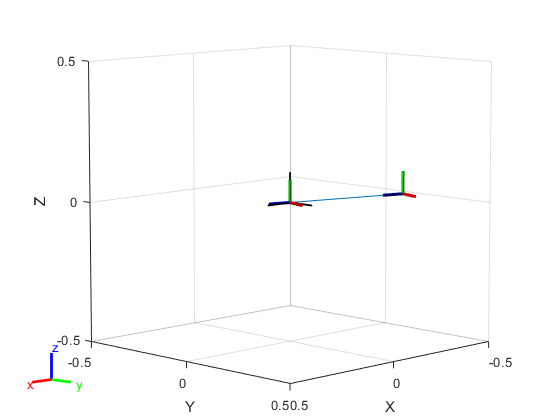

joints = 'RP';
robot_model = build_robot_model(joints, DHTable);

%config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

show(robot_model, randomConfiguration(robot_model));%config);

% KINEMATIC
fprintf("______________________________Direct Kinematic___________________________________\n")

______________________________Direct Kinematic___________________________________


[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
T;
% how to obtain f_r, (i.e. r)
%{
    From DH table:
        A0_2 = A0_1 * A1_2 //mapping from frame 2 to frame 0
    So, to obtain the origin of frame 2 in frame 0:
        O2_2 = [0 0 0] % 3D space
            -> O2_2_H = [0 0 0 1] //homog. transf
        
        r = O0_2 = [rx ry rz 1]' = A0_2*O2_2_H 
%}
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2)]

$$f\_r = \left(\begin{array}{c} q_{2}\,\sin\left(q_{1}\right)\\ -q_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

fprintf("______________________________Inverse Kinematic___________________________________\n")

______________________________Inverse Kinematic___________________________________


syms px py

%positive solution
q2_p=sqrt(px^2 + py^2);
q1_p = atan2(px/q2_p, -py/q2_p);
q_p = [q1_p;q2_p]

$$q\_p = \left(\begin{array}{c} \text{atan2}\left(\frac{\mathrm{px}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}},-\frac{\mathrm{py}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)\\ \sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}} \end{array}\right)$$

    
%negative solution
q2_n = -sqrt(px^2 + py^2);
q1_n = atan2(px/q2_n, -py/q2_n);
q_n = [q1_n;q2_n]

$$q\_n = \left(\begin{array}{c} \text{atan2}\left(-\frac{\mathrm{px}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}},\frac{\mathrm{py}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)\\ -\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}} \end{array}\right)$$

px = -1

px = -1

py = 1

py = 1


q0_p = subs(q_p)

$$q0\_p = \left(\begin{array}{c} -\frac{3\,\pi }{4}\\ \sqrt{2} \end{array}\right)$$

    double(q0_p)

ans =    -2.3562
    1.4142



q0_n = subs(q_n)

$$q0\_n = \left(\begin{array}{c} \frac{\pi }{4}\\ -\sqrt{2} \end{array}\right)$$

    double(q0_n)

ans =     0.7854
   -1.4142


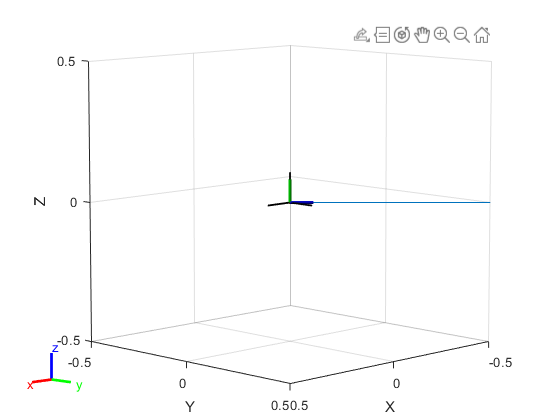

config = build_configuration(robot_model, double(q0_p));
show(robot_model, config);

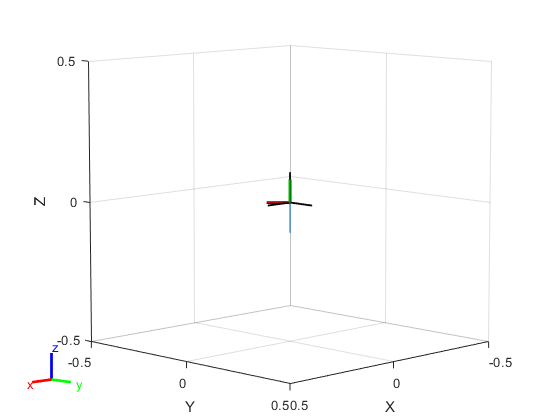

config = build_configuration(robot_model, double(q0_n));
show(robot_model, config);

% DINAMIC
fprintf("______________________________Diff___________________________________\n")

______________________________Diff___________________________________


J = simplify(jacobian(f_r, [q1 q2]))

$$J = \left(\begin{array}{cc} q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) \end{array}\right)$$

ans = 2.0944